# Sine wave interference

https://www.dsprelated.com/showarticle/635.php

clear ; close all ; clc

f = 1; % frequency [Hz]
ratio = 0.6; % amplitude ratio of waves
A1 = 0.8; % amplitude of 1st wave
A2 = ratio * A1; % amplitude of 2nd wave
ph1 = -20; % phase of 1st wave
ph2 = ph1 + 100; % phase of 2nd wave
dph = (ph2 - ph1); % phase difference

Fs = 1000; % sampling frequency [Hz]
T = 3*(1/f); % total time [s]
t = (0:(1/Fs):T)'; % time vector [s]

r = sin(2*pi*f*t); % refernce wave
x1 = A1*sin(2*pi*f*t + deg2rad(ph1)); % 1st wave
x2 = A2*sin(2*pi*f*t + deg2rad(ph2)); % 2nd wave
y = x1 + x2; % sum of waves

% B = sqrt( (A1*cosd(ph1) + A2*cosd(ph2))^(2) + (A1*sind(ph1) + A2*sind(ph2))^(2) );
B = sqrt( A1^(2) + A2^(2) + 2*A1*A2*cosd(dph) );
B_check = max(y);

phi = atand( (A1*sind(ph1) + A2*sind(ph2)) / (A1*cosd(ph1) + A2*cosd(ph2)) );
phi = atand( A2*sind(dph) / (A2*cosd(dph) + A1) );
[Z,fz,mag,phs] = chirpz(y,t,0,Fs/2);
fI = find(fz == f);
phi_check = rad2deg(phs(fI)) + 90;

phase_shift = ph1 - phi

phase_shift = -53.4092

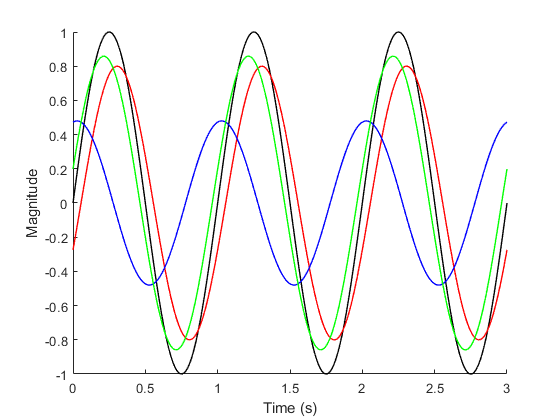


figure (1)
ax = subplot(1,1,1); cla ; hold on
xlabel('Time (s)')
ylabel('Magnitude')
plot(t, r, 'k', 'LineWidth', 1)
plot(t, x1, 'r', 'LineWidth', 1)
plot(t, x2, 'b', 'LineWidth', 1)
plot(t, y, 'g', 'LineWidth', 1)

clear ; close all ; clc

syms A_1 A_2 
